# **Assignment 5**

**EE851 Advanced Digital Communication Systems**

*Instructor: Dr Rizwan Ahmad*

*Prepared by: Ali Hassan*

*Due Date: 3rd Feb, 2020*

*Submitted by: Mahnoor Anjum*

*Registration Number: 330720*

## ***Instructions:***

- *All Question are MATLAB Task. Understanding the question is part of task. Further details about task given in problem statement. *

- *Every student should solve on his own. Plagiarism will result in marks deduction. *

- *Submit your Matlab Task report in soft copy with all your Matlab work (including plots, code, comments etc.). (link create on lms)*

- *Write your own function for different cooperative schemes. Don’t use built-in functions.*

- *Write your own function for QPSK modulation and demodulation. *

## ***Question***

Consider a cooperative network scenario comprising of a source, two relays and a destination. Next implement cooperative communication protocols:

- Amplify and forward

- Decode and forward

- Coded cooperation

Show the performance by plotting the BER curves in Matlab for all the above mentioned schemes for single relay link (choose any relay randomly) and maximum ratio combining (where two relay links are present between source and destination).

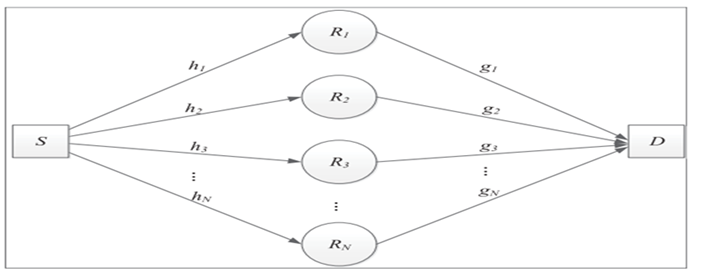

### **Hints**

- For BER plots transmit at least 100000 bits to get smooth curves.

#### Initializations

% Number of bits
n = 10^6;
% For QPSK
bits_per_symbol = 2; 
% Number of symbols 
N = n/bits_per_symbol;
% Powers of source and relays
Pt = 1;
Ps = Pt/3; 
Pr1 = Pt/3;
Pr2 = Pt/3;
% SNR
SNR_db = [0:20];
% the following code provides symbols for QPSK
data_S   = (2*(randi([0,1],1,N))-1) + (1j*(2*(randi([0,1],1,N))-1));
data_D  = zeros(1,N);
unique(data_S')

ans =   -1.0000 - 1.0000i
   1.0000 - 1.0000i
   1.0000 + 1.0000i
  -1.0000 + 1.0000i


- Use QPSK modulation. 

#### QPSK

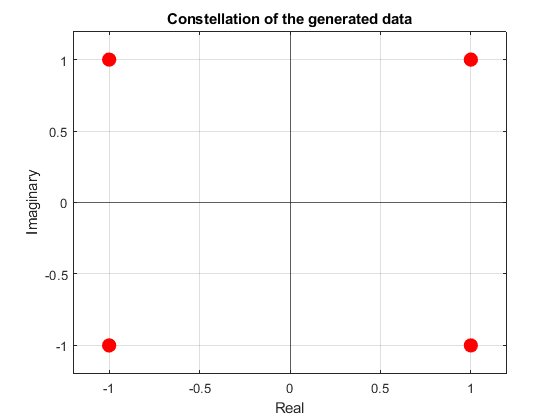

% To confirm QPSK 
plot_qpsk(unique(data_S), "Constellation of the generated data", 10, "r");

- Plot the results for all schemes using channel gains for relay links. Assume AWGN channels.

#### Initializing AWGN 

%AWGN for Soure-Relay1 Link
nsr1 = (1/sqrt(2)).*(randn(1,N)+1j*randn(1,N));
%AWGN for Relay1-Desination Link
nr1d = (1/sqrt(2)).*(randn(1,N)+1j*randn(1,N));
%AWGN for Soure-Relay2 Link
nsr2 = (1/sqrt(2)).*(randn(1,N)+1j*randn(1,N));
%AWGN for Relay2-Desination Link
nr2d = (1/sqrt(2)).*(randn(1,N)+1j*randn(1,N));
%AWGN for Source-Desination Link
nsd = (1/sqrt(2)).*(randn(1,N)+1j*randn(1,N));

#### Initializing Gaussian Channels

- h and g is zero mean complex Gaussian channel. Generate with the help of this command.

 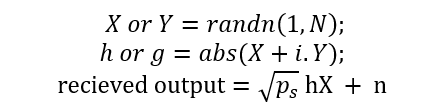

X = randn(1,N); Y = randn(1,N);
% Channel coefficients for Source-Relay1
channel_S_R1= (X+1j*Y);
% Gain for Soure-Relay1
h_S_R1 = ((abs(channel_S_R1)));
X = randn(1,N); Y = randn(1,N);
% Channel coefficients for Source-Relay2
channel_S_R2= (X+1j*Y);
% Gain for Soure-Relay2
h_S_R2 = (abs(channel_S_R2));

X = randn(1,N); Y = randn(1,N);
% Channel coefficients for Relay1-Desination
channel_R1_D = (X+1j*Y);
% Gain for Relay1-Desination
h_R1_D = (abs(channel_R1_D));
X = randn(1,N); Y = randn(1,N);
% Channel coefficients for Relay2-Desination
channel_R2_D = (X+1j*Y);
% Gain for Relay2-Desination
h_R2_D = (abs(channel_R2_D));

X = randn(1,N); Y = randn(1,N);
% Channel coefficients for Soure-Desination
channel_S_D = (X+1j*Y);
% Gain for Soure-Desination
h_S_D = (abs(channel_S_D));
SNR = db2pow(SNR_db);

#### Amplify and Forward

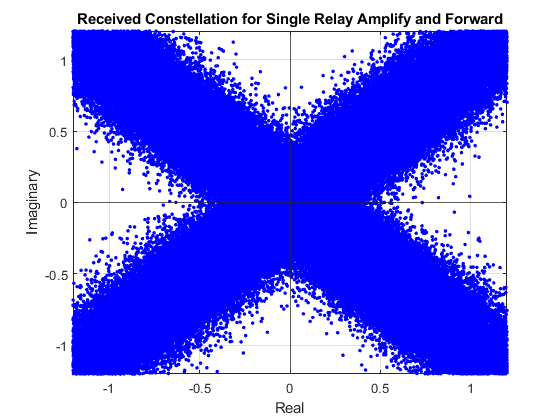

Noise  = zeros(1, length(SNR));
Error_AF_R1  = zeros(1, length(SNR));
Error_AF_R1R2  = zeros(1, length(SNR));

for i=1:length(SNR)
    Noise(i) = Pt./SNR(i);   
    beta1  = sqrt(Pr1./ ((sum(h_S_R1)/N)^2.*Ps+Noise(i)) );
    beta2  = sqrt(Pr2./ ((sum(h_S_R2)/N)^2.*Ps+Noise(i)) );
    % s > r1 > d
    data_S_R1 = sqrt(Ps/2) .* data_S .* h_S_R1 + sqrt(Noise(i))*nsr1;
    data_R1_D = beta1 .* data_S_R1 .* h_R1_D + sqrt(Noise(i))*nr1d;
    % s > r2 > d
    data_S_R2 = sqrt(Ps/2) .* data_S .* h_S_R2 + sqrt(Noise(i))*nsr2;
    data_R2_D = beta2 .* data_S_R2 .* h_R1_D + sqrt(Noise(i))*nr2d;
        
    % Maximum Ratio Combining    
    data_raw_r1 = data_R1_D;
    
    data_raw_r1r2 = (data_R1_D .* conj(channel_S_R1 .* channel_R1_D)  + ... 
                    (data_R2_D .* conj(channel_S_R2 .* channel_R2_D)));
    [data_D_R1, Error_AF_R1(i)] = demod_qpsk(data_S, data_raw_r1);
    [data_D_R2, Error_AF_R1R2(i)] = demod_qpsk(data_S, data_raw_r1r2);
end

% Plot received data
plot_qpsk(data_raw_r1, "Received Constellation for Single Relay Amplify and Forward", 2, "b");

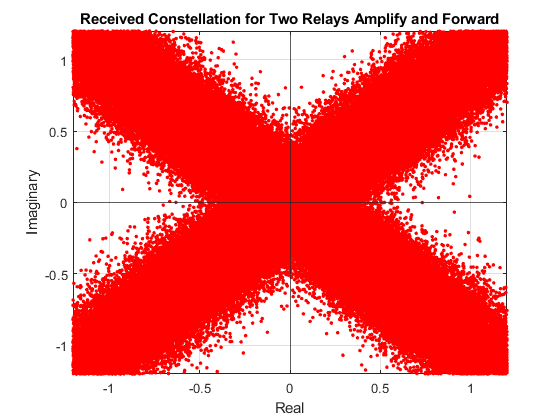

plot_qpsk(data_raw_r1, "Received Constellation for Two Relays Amplify and Forward", 2, "r");

#### Decode and Forward

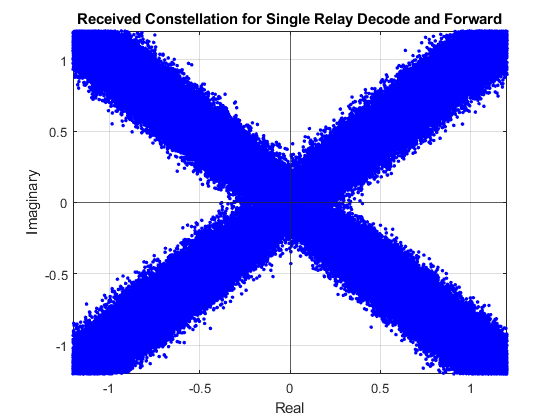

Noise  = zeros(1, length(SNR));
Error_DF_R1  = zeros(1, length(SNR));
Error_DF_R1R2  = zeros(1, length(SNR));

for i=1:length(SNR)
    Noise(i) = Pt./SNR(i);   
    beta1  = sqrt(Pr1./ ((sum(h_S_R1)/N)^2.*Ps+Noise(i)) );
    beta2  = sqrt(Pr2./ ((sum(h_S_R2)/N)^2.*Ps+Noise(i)) );
    % s > r1 > d
    data_S_R1 = sqrt(Ps/2) .* data_S .* h_S_R1 + sqrt(Noise(i))*nsr1;
    [data_R1_decode, temp] = demod_qpsk(data_S, data_S_R1);
    data_R1_D = beta1 .* data_R1_decode .* h_R1_D + sqrt(Noise(i))*nr1d;
    % s > r2 > d
    data_S_R2 = sqrt(Ps/2) .* data_S .* h_S_R2 + sqrt(Noise(i))*nsr2;
    [data_R2_decode, temp] = demod_qpsk(data_S, data_S_R2);
    data_R2_D = beta2 .* data_R2_decode .* h_R1_D + sqrt(Noise(i))*nr2d;
    
    % data_S_D = sqrt(Ps/2) .* data_S .* h_S_D + sqrt(Noise(i))*nsd;
    
    % Maximum Ratio Combining
    % data_raw_r1 = (data_S_D .* conj(channel_S_D)) + ... 
    %           (data_R1_D .* conj(channel_S_R1 .* channel_R1_D));
    
    data_raw_r1 = data_R1_D;
    
    data_raw_r1r2 = (data_R1_D .* conj(channel_S_R1 .* channel_R1_D)  + ... 
                    (data_R2_D .* conj(channel_S_R2 .* channel_R2_D)));
    [data_D_R1, Error_DF_R1(i)] = demod_qpsk(data_S, data_raw_r1);
    [data_D_R2, Error_DF_R1R2(i)] = demod_qpsk(data_S, data_raw_r1r2);
end

% Plot received data
plot_qpsk(data_raw_r1, "Received Constellation for Single Relay Decode and Forward", 2, "b");

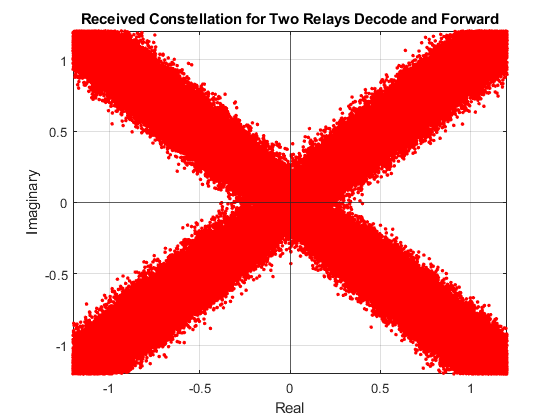

plot_qpsk(data_raw_r1, "Received Constellation for Two Relays Decode and Forward", 2, "r");

- Plot the BER for single relay and maximum ratio combining vs. average SNR (0:1:20 dB)

#### BER Plot

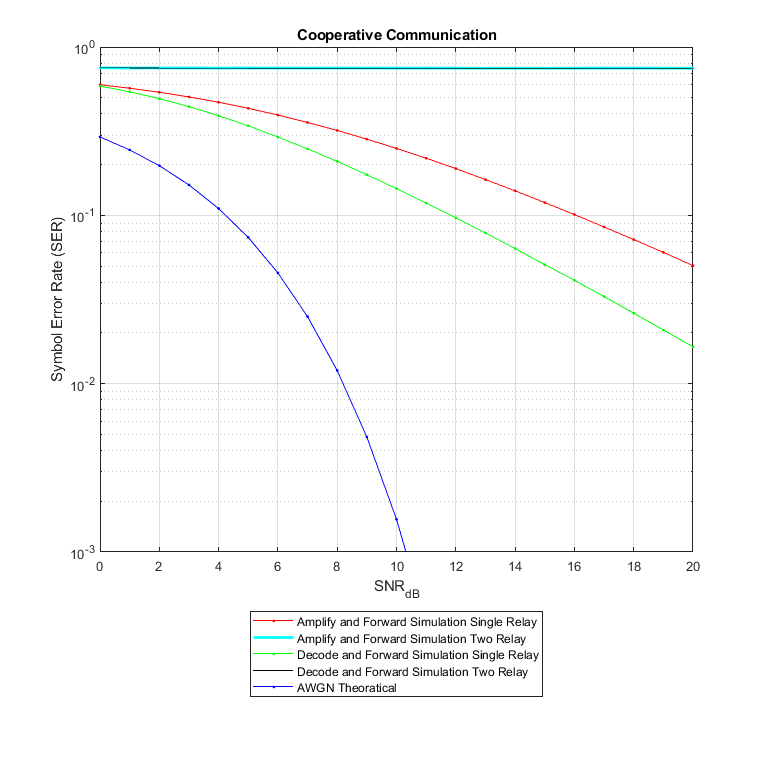

figure('Renderer', 'painters', 'Position', [10 10 900 900]),
BER_AF_R1=Error_AF_R1/N;
semilogy(SNR_db,BER_AF_R1,'r.-')
hold on, grid on, box on, axis([0 20 10^-3 10^0])
BER_AF_R1R2=Error_AF_R1R2/N;
semilogy(SNR_db,BER_AF_R1R2,'c.-', 'linew', 2)
BER_DF_R1=Error_DF_R1/N;
semilogy(SNR_db,BER_DF_R1,'g.-')
BER_DF_R1R2=Error_DF_R1R2/N;
semilogy(SNR_db,BER_DF_R1R2,'k')
% https://dsp.stackexchange.com/questions/46013/
BER_QPSK_IDEAL = erfc(sqrt(0.5*(10.^(SNR_db/10)))) - ...
    (1/4)*(erfc(sqrt(0.5*(10.^(SNR_db/10))))).^2;
semilogy(SNR_db,BER_QPSK_IDEAL,'b.-'); 
xlabel('SNR_d_B');
ylabel('Symbol Error Rate (SER)');
title('Cooperative Communication')
l = legend('Amplify and Forward Simulation Single Relay', ... 
           'Amplify and Forward Simulation Two Relay',...
           'Decode and Forward Simulation Single Relay', ...
           'Decode and Forward Simulation Two Relay',...
           'AWGN Theoratical');
l.Location = 'southoutside';

- For coded cooperation choose a channel coding scheme and share its information.

#### Network Coding

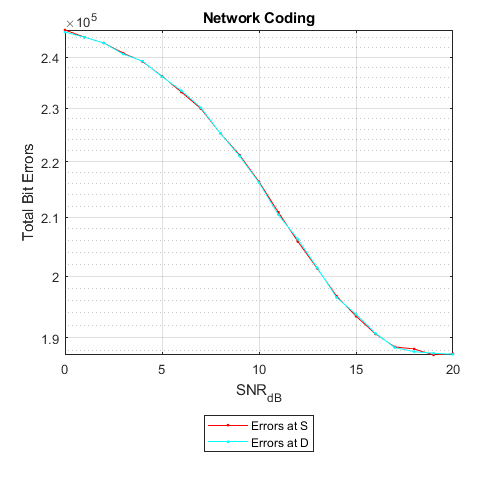

%AWGN for Soure-Relay1 Link
nsr1 = randn(1,N);
%AWGN for Relay1-Desination Link
nr1d = randn(1,N);
%AWGN for Soure-Relay2 Link
nsr2 = randn(1,N);
%AWGN for Relay2-Desination Link
nr2d = randn(1,N);
%AWGN for Source-Desination Link
nsd = randn(1,N);
Noise  = zeros(1, length(SNR));
Error_CC_R1  = zeros(1, length(SNR));
Error_CC_R1R2  = zeros(1, length(SNR));
% Using BPSK
data_S = randi([0,1],1,N);
data_D = randi([0,1],1,N);
Pt = 1; Ps = Pt/4; Pr = Pt/4; Pd = Pt/4; 
for i=1:length(SNR)
    data_S = randi([0,1],1,N);
    data_D = randi([0,1],1,N);
    Noise(i) = Pt./SNR(i);   
    beta1  = sqrt(Pr1./ ((sum(h_S_R1)/N)^2.*Ps+Noise(i)) );
    beta2  = sqrt(Pr2./ ((sum(h_S_R2)/N)^2.*Ps+Noise(i)) );
    % s > r1 > d
    data_S_R1 = sqrt(Ps/2) .* data_S + sqrt(Noise(i))*nsr1;
    % d > r1 > s
    data_D_R1 = sqrt(Pd/2) .* data_D + sqrt(Noise(i))*nr1d;
    % r1 > s  & r1 > d
    data_XOR = double(xor((data_D_R1>0), (data_S_R1>0)));
    data_R1_D = sqrt(Pr) .* data_XOR + sqrt(Noise(i))*nr1d;
    data_R1_S = sqrt(Pr) .* data_XOR + sqrt(Noise(i))*nsr1;
    
    data_XOR_at_S = double(xor((data_S>0), (data_R1_S>0)));
    data_XOR_at_D = double(xor((data_D>0), (data_R1_D>0)));

    [Error_CC_S(i)] = sum(data_XOR_at_S ~= data_D);
    [Error_CC_D(i)] = sum(data_XOR_at_D ~= data_S);
end
figure('Renderer', 'painters', 'Position', [10 10 500 500]),
semilogy(SNR_db,Error_CC_S,'r.-')
hold on, grid on, box on
semilogy(SNR_db,Error_CC_D,'c.-')
xlabel('SNR_d_B');
ylabel('Total Bit Errors');
title('Network Coding')
l = legend('Errors at S', ... 
           'Errors at D');
l.Location = 'southoutside';

### **Report**

**Report to include:**

- Screen shots of BER curves for QPSK modulation comparing all cooperative communication schemes. 

- Code to show working of different cooperative communications schemes.

- QPSK Constellation plots (both transmitter side and receiver side) + BER for complete system integration + code

## Helper Functions

function [data_r, error] = demod_qpsk(data, data_raw)
    a=real(data_raw);
    b=imag(data_raw);
    data_r(find(a>=0 & b>=0)) = 1+1*1j;
    data_r(find(a>=0 & b<0))  = 1-1*1j;
    data_r(find(a<0 & b>=0))  = -1+1*1j;
    data_r(find(a<0 & b<0))   = -1-1*1j;     
    error=size(find((data- data_r)),2);
end

function handle = plot_qpsk(data, string, size, color)
    figure(); hold on; grid on; box on;
    xline(0); yline(0); xlim([-1.2, 1.2]); ylim([-1.2, 1.2]);
    xlabel("Real"); ylabel("Imaginary")
    plot(data, 'o','MarkerSize', size, 'MarkerFaceColor',color, "MarkerEdgeColor",color);
    title(string)
    handle = gcf;
end

